# Steering Control

#### SEED Lab                Alex Curtis

*Upload the stepResponse code to the Arduino before running.*

## Summary

This live script does the following:

- Communicates with the Arduino over serial

- Runs two experiments that show the characteristics of how the robot drives in a straight path and how it rotates

- Validates the experimental step response data from the Arduino

- Filters noise from the data

- Analyzes the data to determine the transfer functions of the robot

- Validates the transfer functions graphically

- Creates a controller for each transfer function using the transfer functions 

- Outputs the Kp, Ki, and Kd constants for each controller in a format that can be easily implemented in the Arduino

#### Important Variables

#### $\dot{\rho}_d$    (rho dot)             

The forward velocity of the robot (inches/sec) 

#### $\rho_d$    (rho)

The forward position of the robot  (inches)

#### $\dot{\phi}$      (phi dot)   

The angular velocity of the robot (radians/sec)

#### $\phi$      (phi)

The angular position of the robot (radians)

#### Important Equations

### 
$$\overline{V}_{a} = V_{a,1} + V_{a,2}$$


$\overline{V}_a$ is the sum of the left and right motor voltage commands. 

In the range [-400, 400] with 400 representing full forward speed

#### 
$$\Delta{V}_{a} = V_{a,1} - V_{a,2}$$


$\Delta V_a$ is the difference between the left and right motor voltage commands. 

In the range [-400,400] with 400 representing spinning clockwise at full speed 

#### Transfer functions to find:

### 
$$G_{\rho}(s) = \frac{\rho(s)}{\overline{V}_a(s)}$$


Forward position to the combined voltage commands

### 
$$G_{\phi}(s) = \frac{\phi(s)}{\Delta V_a(s)}$$


Angular position to the difference between the voltage commands

#### Clear previous workspace data

clear

#### Automatically find the port the Arduino is connected to

allPorts = serialportlist;  % list of all available ports
pat = "/dev/cu.usbmodem";   % text to look for

% logical array of matching ports
matchingPorts = startsWith(allPorts, pat);   

if any(matchingPorts)                   % If any matches were found,              
    numMatches = sum(matchingPorts);    % Count the number of matches.
    if size(numMatches) > 1             % If multiple matching ports were found, 
        error("Multiple ports found")   % throw an error.
    else                                % If only one match was found,
        port = allPorts(matchingPorts); % that string is the arduino port.
    end
else                                    % If no ports were found,
    error("Port not found")             % throw an error.
end

## Run Experiment 1 (forward velocity)

#### Create a serialport object to talk to the Arduino for the first experiment

ard = serialport(port, 115200);   % creates a device object (port, baud)
configureTerminator(ard, "CR/LF") % sets the terminator

#### Wait for the Arduino

When the Arduino is ready, it sends "Start!"

readline(ard)

ans = "Start!"

#### Tell the Arduino to start the forward velocity experiment (#1)

disp('Starting forward velocity experiment in Arduino')

Starting forward velocity experiment in Arduino


writeline(ard,"1"); % sends the start command to the Arduino

Read data from Arduino

k = 0; % array index
% stringArray = zeros(1001,5); % preallocate

% Read the first line of output from the Arduino
newData = readline(ard);

% Read new data until the Arduino signals it's done
while (~strncmp(newData,'Finished1',9)) 
    k = k + 1; % k++

    % save the line of text to stringArray(k)
    stringArray(k,:) = split(newData)';

    % Read a new line of data from Arduino
    newData = readline(ard);
end
clear newData ard; % Disconect from the Arduino

% change string data to cell array using tab delimiter 
dataArray = str2double(stringArray);

% Make time start at 0 and convert from ms to s
dataArray(:,1) = (dataArray(:,1)-1000)/1000;

% Save experiment 1 data to the exp1 data table
exp1 = array2table(dataArray,"VariableNames",{'time', 'posL', 'posR', 'fVel', 'rVel'});
save steerData.mat exp1
clear dataArray stringArray newData

## Run Experiment 2 (angular velocity)

#### Create a serialport object to talk to the Arduino for the second experiment

ard = serialport(port, 115200);   % creates a device object (port, baud)
configureTerminator(ard, "CR/LF") % sets the terminator

#### Wait for the Arduino

When the Arduino is ready, it sends "Start!"

readline(ard)

ans = "Start!"

#### Tell the Arduino to start the rotational velocity experiment (#2)

disp('Starting rotational velocity experiment in Arduino')

Starting rotational velocity experiment in Arduino


writeline(ard,"2") % sends the start command to the Arduino

Read data from Arduino

k2 = 0; % array index

% Read the first line of output from the Arduino
newData = readline(ard);

% Read new data until the Arduino signals it's done
while (~strncmp(newData,'Finished2',9)) 
    k2 = k2 + 1; % k++

    % save the line of text to stringArray(k)
    stringArray(k2,:) = split(newData)';

    % Read a new line of data from Arduino
    newData = readline(ard);
end

clear ard; % Disconect from the Arduino

% change string data to cell array using tab delimiter 
dataArray = str2double(stringArray);

% Make time start at 0 and convert from ms to s
dataArray(:,1) = (dataArray(:,1)-1000)/1000;

% Save experiment 2 data to the exp2 data table
exp2 = array2table(dataArray,"VariableNames",{'time', 'posL', 'posR', 'fVel', 'rVel'});

## Verify the velocity data from the Arduino

The values sent from the Arduino aren't as consistent as what Matlab can do.

WHEEL_RADIUS = 2.95;              % Radius of wheel in inches
WHEELBASE = 13.974;
rho_dot1(k,1) = 0;
phi_dot1(k,1) = 0;
rho_dot2(k2,1) = 0;
phi_dot2(k2,1) = 0;
CONVERSION = (WHEEL_RADIUS*2.0*pi)/3200;
for i = 2:k
    rho_dot1(i,1) = CONVERSION*(exp1.posR(i) - exp1.posR(i-1) + exp1.posL(i) - exp1.posL(i-1))/(2.0*(exp1.time(i)-exp1.time(i-1)));
    phi_dot1(i,1) = CONVERSION*(exp1.posL(i) - exp1.posL(i-1) - exp1.posR(i) + exp1.posR(i-1))/(WHEELBASE*(exp1.time(i)-exp1.time(i-1)));
end

for i = 2:k2
    rho_dot2(i,1) = CONVERSION*(exp2.posR(i) - exp2.posR(i-1) + exp2.posL(i) - exp2.posL(i-1))/(2.0*(exp2.time(i)-exp2.time(i-1)));
    phi_dot2(i,1) = CONVERSION*(exp2.posL(i) - exp2.posL(i-1) - exp2.posR(i) + exp2.posR(i-1))/(WHEELBASE*(exp2.time(i)-exp2.time(i-1)));
end

exp1.newRho = rho_dot1;
exp1.newPhi = phi_dot1

exp1 = 101×7 table
    time    posL    posR     fVel      rVel      newRho     newPhi  
    ____    ____    ____    ______    _______    ______    _________

       0      0       0          0          0         0            0
    0.01      3       3     1.8817          0    1.7377            0
    0.02     12      11     5.3314     0.0456    4.9235     0.041451
    0.03     21      22     6.2723    -0.0912    5.7923    -0.082901
    0.04     34      37     8.7812    -0.0912    8.1092    -0.082901
    0.05     50      53     10.036          0    9.2677            0
    0.06     69      73     12.231    -0.0456    11.295    -0.041451
    0.07     88      92     11.917          0    11.005            0
    0.08    110     115     14.113    -0.0456    13.

exp2.newRho = rho_dot2;
exp2.newPhi = phi_dot2

exp2 = 101×7 table
    time    posL    posR     fVel       rVel      newRho     newPhi 
    ____    ____    ____    _______    ______    ________    _______

       0      0        0          0         0           0          0
    0.01      3       -2     0.3136    0.2281     0.28962    0.20725
    0.02     12      -10     0.3136    0.7755     0.28962    0.70466
    0.03     23      -21          0    1.0036           0    0.91191
    0.04     36      -34          0     1.186           0     1.0777
    0.05     52      -51    -0.3136    1.5053    -0.28962     1.3679
    0.06     71      -71    -0.3136     1.779    -0.28962     1.6166
    0.07     93      -93          0    2.0071           0     1.8238
    0.08    113     -114    -0.3136    1.8703    -0.

### Compare the data Matlab calculated with what the Arduino sent

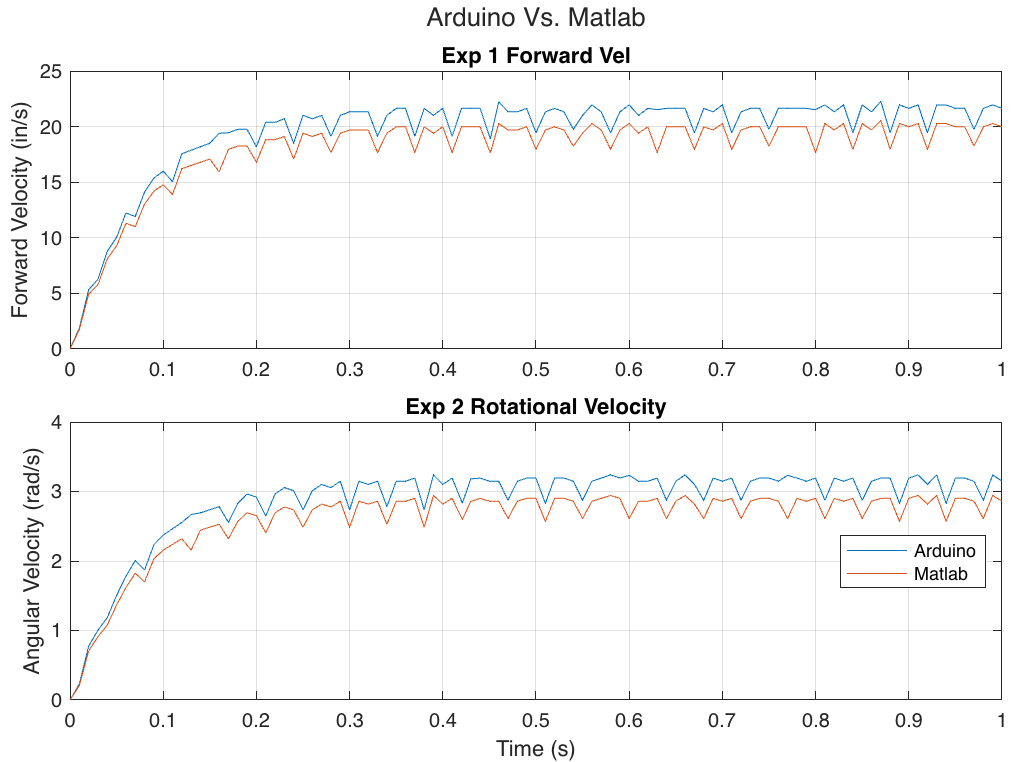

t = tiledlayout(2,1,'TileSpacing','Compact','Padding','tight');
title(t,'Arduino Vs. Matlab')

nexttile;
plot(exp1.time,exp1.fVel,exp1.time,exp1.newRho);
title('Exp 1 Forward Vel');
ylabel('Forward Velocity (in/s)');
grid on;

nexttile;
plot(exp2.time, exp2.rVel,exp2.time,exp2.newPhi);
title('Exp 2 Rotational Velocity');
legend('Arduino','Matlab','Location','east');
ylabel('Angular Velocity (rad/s)');
grid on

xlabel('Time (s)')

### Clean and Scale the velocity data

Smoothing the velocity data gets rid of any noise that might mess up the resulting transfer functions.

new1 = exp1;
new2 = exp2;

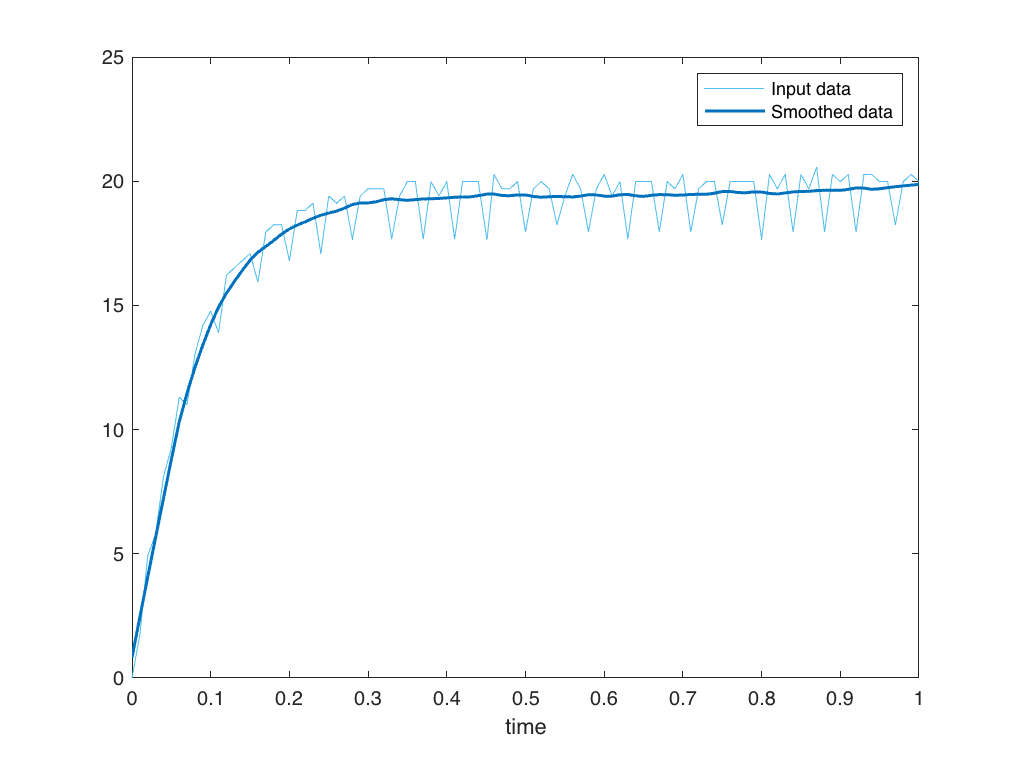

% Smooth input data
smoothedRho = smoothdata(exp1.newRho,"lowess","SmoothingFactor",0.4,...
    "SamplePoints",exp1.time);

% Display results
clf
plot(exp1.time,exp1.newRho,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(exp1.time,smoothedRho,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")

new1.newRho = smoothedRho;

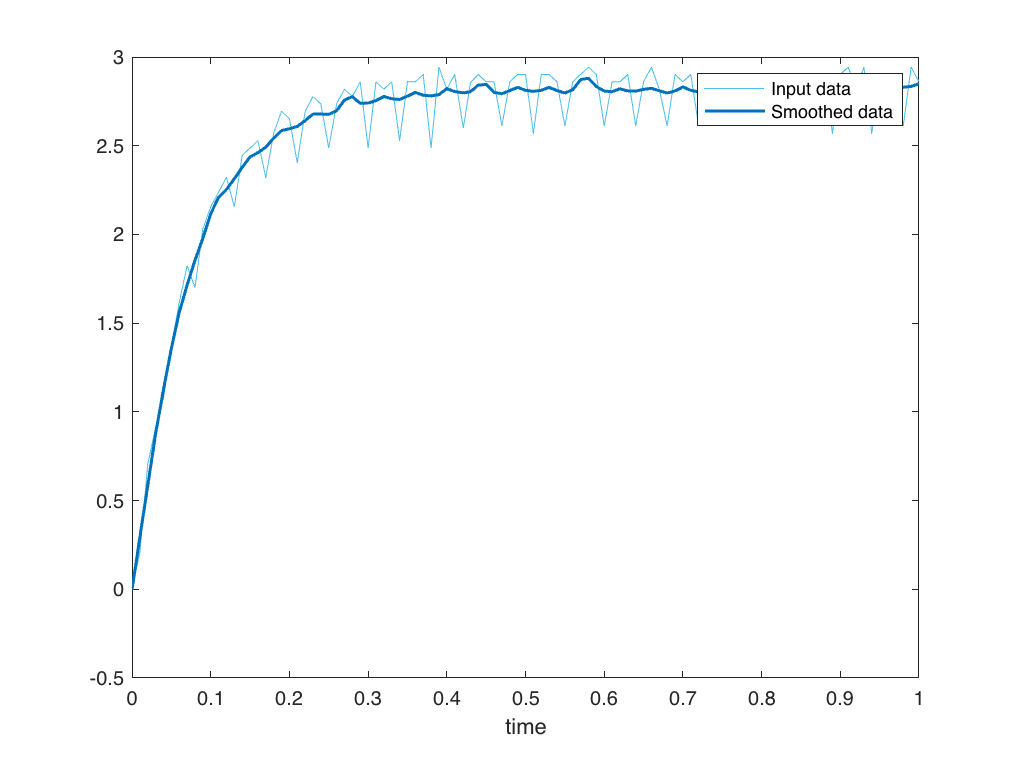

% Smooth input data
smoothedPhi = smoothdata(exp2.newPhi,"lowess","SmoothingFactor",0.25,...
    "SamplePoints",exp2.time);

% Display results
clf
plot(exp2.time,exp2.newPhi,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(exp2.time,smoothedPhi,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")

new2.newPhi = smoothedPhi;

max motor.setM1Speed() command = 400

Since the motor command sum is a number out of 400, I need to divide the forward velocity by 400 to get a unit step response.

The maximum motor command difference is 400, corresponding to -400 and 400 on each motor. The rotational velocity needs to be divided by 400

new1.newRho = new1.newRho/400; new2.newPhi = new2.newPhi/400;

## Determine K and sigma for each experiment

Find the steady state velocity of the motor (K)

K_rho = new1.newRho(new1.time > 0.4); K_phi = new2.newPhi(new2.time > 0.4);
K_rho = mean(K_rho), K_phi = mean(K_phi)

K_rho = 0.0488

K_phi = 0.0071

#### Find 0.64 * K and the time constant to find the values of sigma.

% Find 0.64K
K_rho64 = 0.64*K_rho;
K_phi64 = 0.64*K_phi;

% Find the closest match to 0.64K in each set of data
[~,idxRho] = min( abs(new1.newRho-K_rho64) );
magAt64K_rho = new1.newRho(idxRho)

magAt64K_rho = 0.0313

[~,idxPhi]=min(abs(new2.newPhi-K_phi64));
magAt64K_phi=new2.newPhi(idxPhi)

magAt64K_phi = 0.0046


% 0.64K corresponds to the location of the time constant (1/sigma)
TC_rho = new1.time(new1.newRho == magAt64K_rho);
TC_phi = new2.time(new2.newPhi == magAt64K_phi);

% We found sigma!
sigmaRho = 1/TC_rho

sigmaRho = 12.5000

sigmaPhi = 1/TC_phi

sigmaPhi = 12.5000

#### Plot the processed data (motor unit step response)

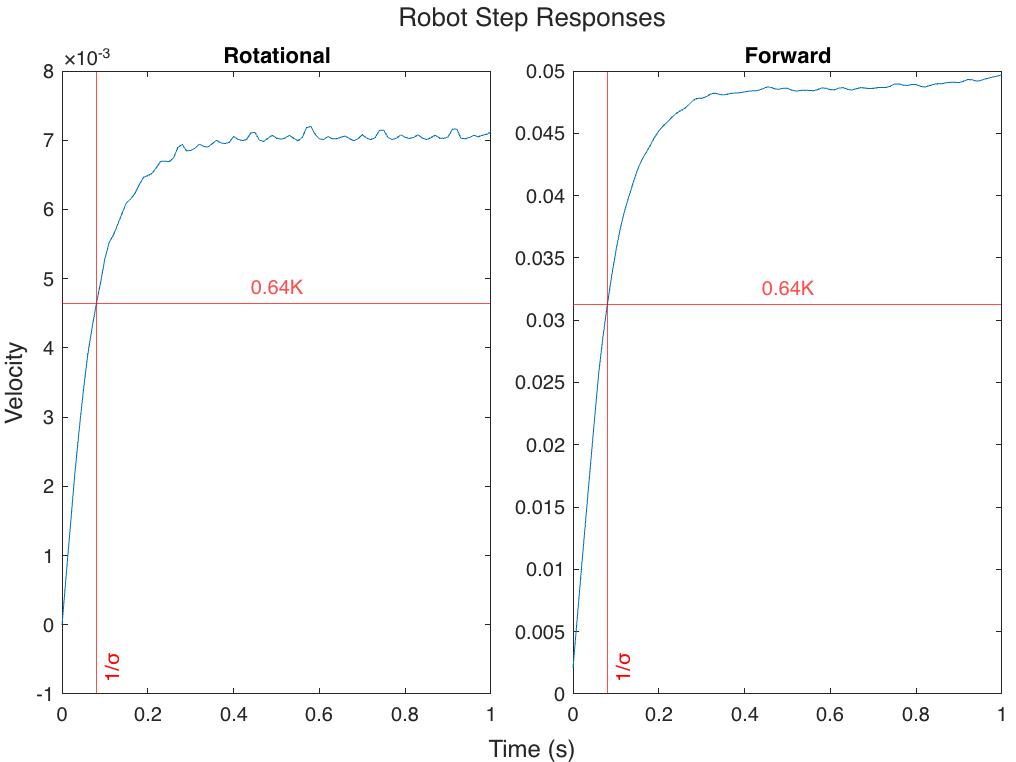

t2 = tiledlayout(1,2,"TileSpacing","compact",'Padding','tight');
xlabel(t2, 'Time (s)')
ylabel(t2, 'Velocity')
title(t2, 'Robot Step Responses')

nexttile
plot(new2.time,new2.newPhi)
title('Rotational')
yline(magAt64K_phi,'Label','0.64K','Color','r',LabelHorizontalAlignment='center')
xline(TC_phi,'Label','1/\sigma','Color','r','LabelVerticalAlignment','bottom')

nexttile
plot(new1.time,new1.newRho)
title('Forward')
yline(magAt64K_rho,'Label','0.64K','Color','r',LabelHorizontalAlignment='center')
xline(TC_rho,'Label','1/\sigma','Color','r','LabelVerticalAlignment','bottom')

## Create the velocity and position transfer functions

With the sigma and K values for each experiment, I can create first order transfer functions that represent the response of the robot

s = tf('s');

% Find the velocity transfer functions
rho_velTF = K_rho*(sigmaRho)/(s+sigmaRho);
rho_velTF.InputName = "Command Sum";
rho_velTF.OutputName = "Forward Velocity";
rho_velTF.OutputUnit = "inches/s"

rho_velTF =
 
  From input "Command Sum" to output "Forward Velocity":
    0.61
  --------
  s + 12.5
 
Continuous-time transfer function.




phi_velTF = K_phi*(sigmaPhi)/(s+sigmaPhi);
phi_velTF.InputName = "Command Difference";
phi_velTF.OutputName = "Rotational Velocity";
phi_velTF.OutputUnit = "rad/s"

phi_velTF =
 
  From input "Command Difference" to output "Rotational Velocity":
  0.08815
  --------
  s + 12.5
 
Continuous-time transfer function.




% Position is the integral of velocity, and 1/s represents an integral.
rho_posTF = rho_velTF*(1/s);
rho_posTF.InputName = "Command Sum";
rho_posTF.OutputName = "Forward Position";
rho_posTF.OutputUnit = "inches"

rho_posTF =
 
  From input "Command Sum" to output "Forward Position":
      0.61
  ------------
  s^2 + 12.5 s
 
Continuous-time transfer function.




phi_posTF = phi_velTF*(1/s);
phi_posTF.InputName = "Command Difference";
phi_posTF.OutputName = "Rotational Position";
phi_posTF.OutputUnit = "radians"

phi_posTF =
 
  From input "Command Difference" to output "Rotational Position":
    0.08815
  ------------
  s^2 + 12.5 s
 
Continuous-time transfer function.



#### Turn the generated transfer functions into coefficient arrays I can use in Simulink

posNum_rho = rho_posTF.Numerator;       % Find the numerator coefficients
posNum_rho = posNum_rho{1};             % Convert the numerator to a the right form
posDen_rho = rho_posTF.Denominator;     % Find the denominator coefficients
posDen_rho = posDen_rho{1};             % Convert the denominator to a the right form

velNum_rho = rho_velTF.Numerator;       % Find the numerator coefficients
velNum_rho = velNum_rho{1};             % Convert the numerator to a the right form
velDen_rho = rho_velTF.Denominator;     % Find the denominator coefficients
velDen_rho = velDen_rho{1};             % Convert the denominator to a the right form

posNum_phi = phi_posTF.Numerator;       % Find the numerator coefficients
posNum_phi = posNum_phi{1};             % Convert the numerator to a the right form
posDen_phi = phi_posTF.Denominator;     % Find the denominator coefficients
posDen_phi = posDen_phi{1};             % Convert the denominator to a the right form

velNum_phi = phi_velTF.Numerator;       % Find the numerator coefficients
velNum_phi = velNum_phi{1};             % Convert the numerator to a the right form
velDen_phi = phi_velTF.Denominator;     % Find the denominator coefficients
velDen_phi = velDen_phi{1};             % Convert the denominator to a the right form

## Compare the velocity transfer functions with the actual velocity of the robot

The closer they match, the more accurately the transfer functions represent the robot

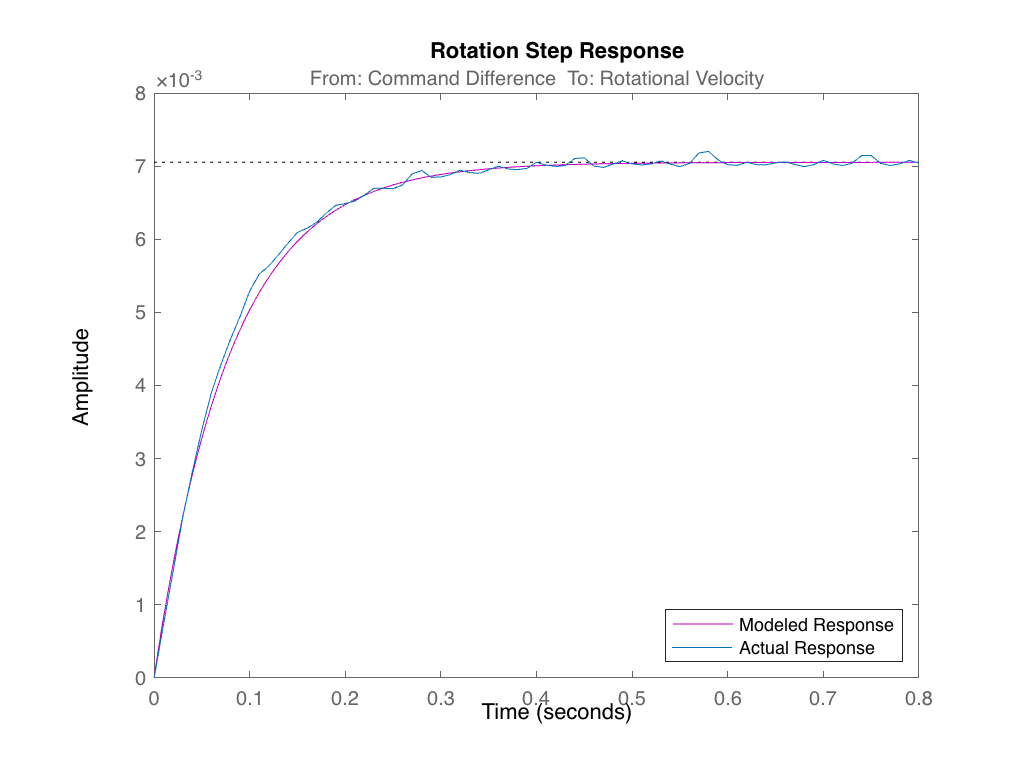

figure
stepplot(phi_velTF,'m')
hold on
plot(new2.time,new2.newPhi)
title("Rotation Step Response")
legend('Modeled Response','Actual Response','Location','southeast')
hold off

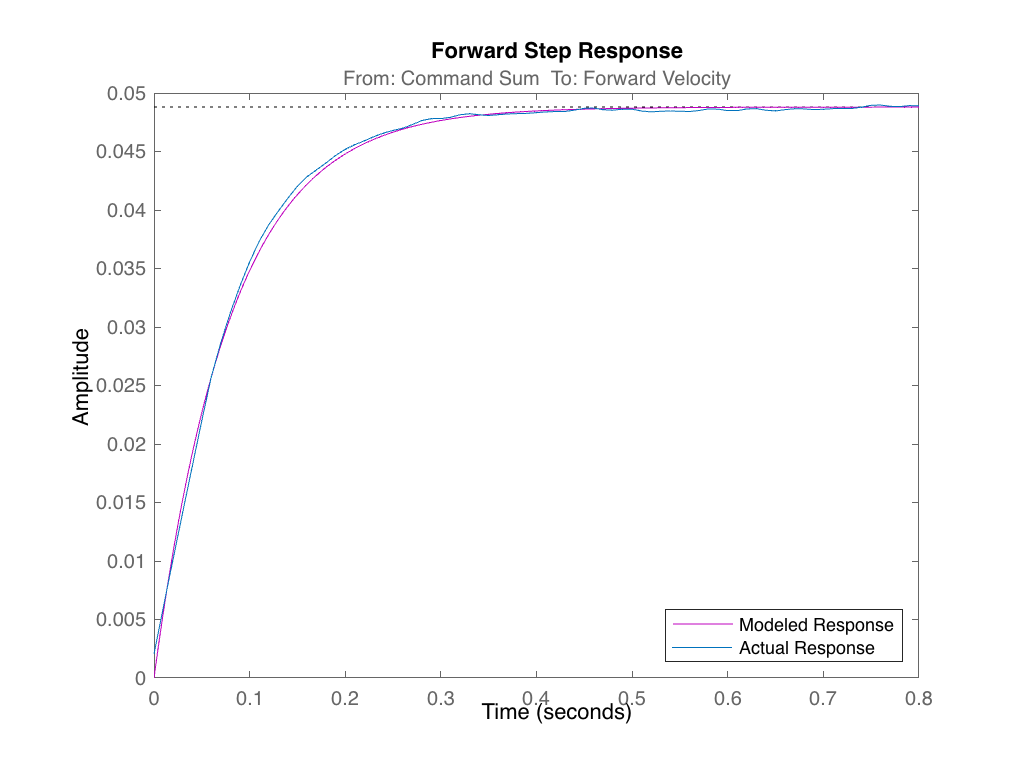


stepplot(rho_velTF,'m')
hold on
plot(new1.time,new1.newRho)
title("Forward Step Response")
legend('Modeled Response','Actual Response','Location','southeast')
hold off

figure

## Design controllers to regulate position

### Make a controller for forward position (rho)

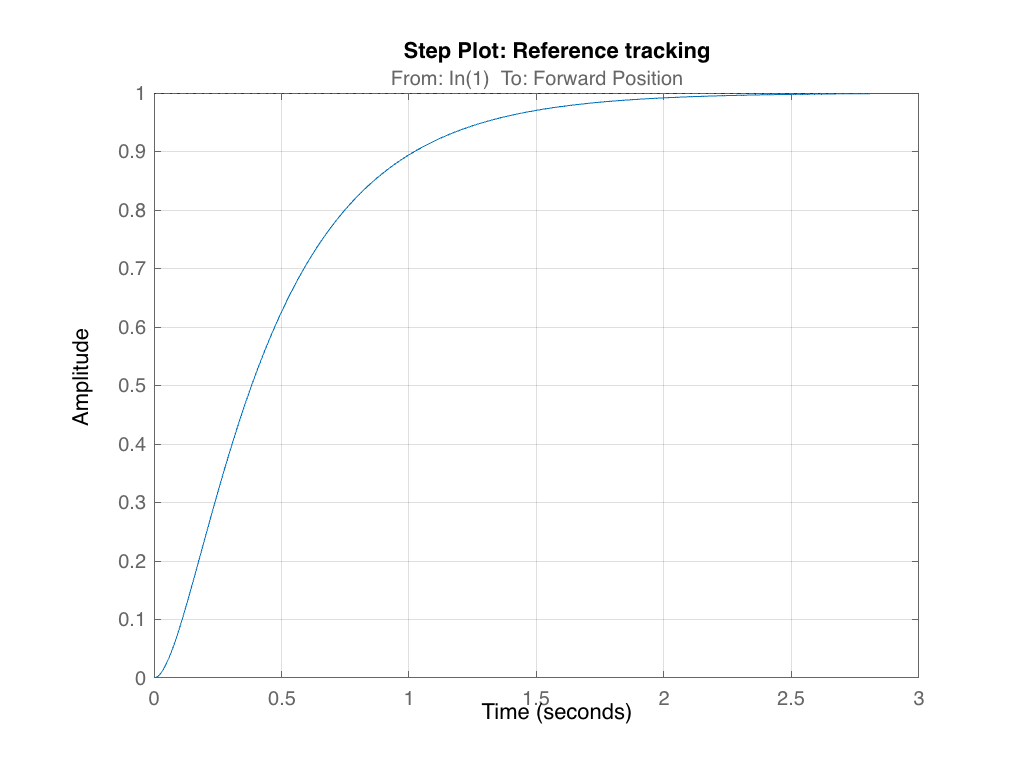

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc2 = 2/1;

% PID tuning algorithm for linear plant model
[C_rho,pidInfo] = pidtune(posTF_rho,'P',wc2);

% Clear Temporary Variables
clear wc2

% Get desired loop response
Response = getPIDLoopResponse(C_rho,posTF_rho,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Display system response characteristics
disp(stepinfo(Response))

         RiseTime: 0.9111
    TransientTime: 1.6545
     SettlingTime: 1.6545
      SettlingMin: 0.9013
      SettlingMax: 0.9997
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9997
         PeakTime: 3.3207




% Clear Temporary Variables
clear Response

### Make a controller for angular position (phi)

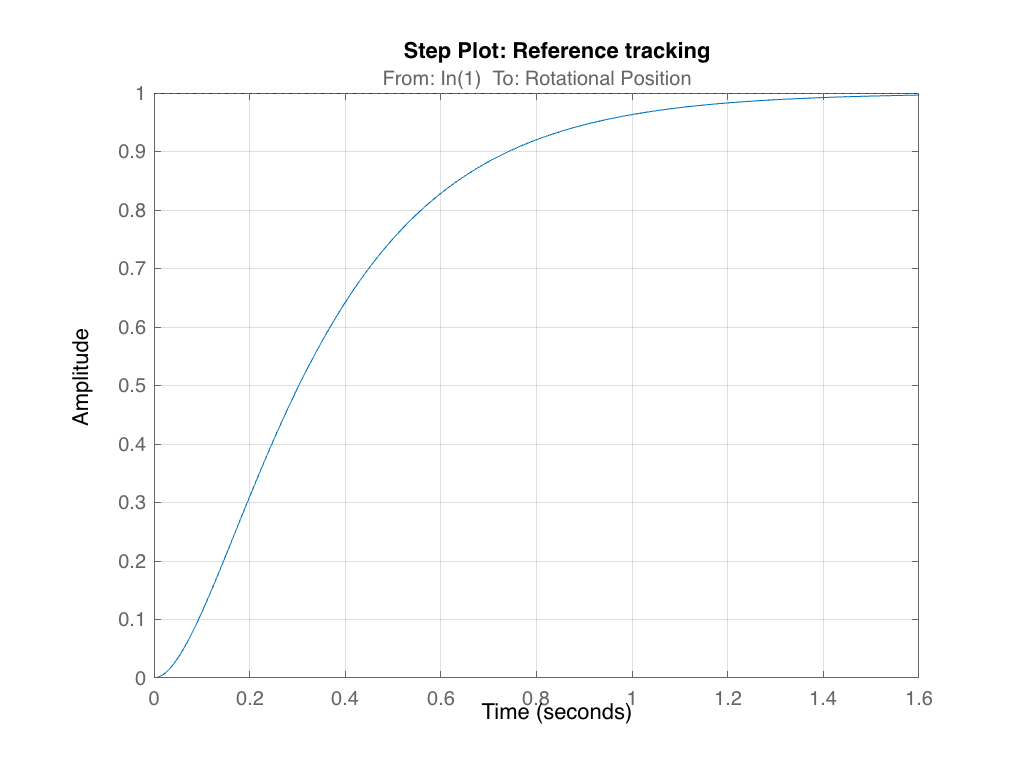

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/0.761527;

% Define options for pidtune command
opts = pidtuneOptions('DesignFocus','reference-tracking');

% PID tuning algorithm for linear plant model
[C_phi,pidInfo2] = pidtune(posTF_phi,'P',wc,opts);

% Clear Temporary Variables
clear wc opts

% Get desired loop response
Response2 = getPIDLoopResponse(C_phi,posTF_phi,'closed-loop');

% Plot the result
stepplot(Response2)
title('Step Plot: Reference tracking')
grid on


% Display system response characteristics
disp(stepinfo(Response2))

         RiseTime: 0.6486
    TransientTime: 1.1573
     SettlingTime: 1.1573
      SettlingMin: 0.9031
      SettlingMax: 0.9990
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9990
         PeakTime: 1.9173




% Clear Temporary Variables
clear Response2

### Display the Kp, Ki, and Kd values for each new controller

KP_rho = C_rho.Kp; KI_rho = C_rho.Ki; KD_rho = C_rho.Kd;
KP_phi = C_phi.Kp; KI_phi = C_phi.Ki; KD_phi = C_phi.Kd;
fprintf('const float KP_RHO = %f, KI_RHO = %f, KD_RHO = %f;\n',KP_rho, KI_rho,KD_rho)

const float KP_RHO = 41.507628, KI_RHO = 0.000000, KD_RHO = 0.000000;


fprintf('const float KP_PHI = %f, KI_PHI = %f, KD_PHI = %f;\n',KP_phi, KI_phi,KD_phi)

const float KP_PHI = 380.556400, KI_PHI = 0.000000, KD_PHI = 0.000000;
